# CONTINUOUS BEAM IN 2-D

## Solve a cantilever beam in 2-D plane loaded with a vertical point load.

Create a *static-planeframe* model

clc; clear; close all; %clear and close all fig
cantileverBeamModel = saplab.create('attributes','static-planeframe');

Model the cantilever beam geometry

Length = 100; %mm
lineID = saplab.addline(cantileverBeamModel, 'Coordinates', [0,0],[Length,0]);

Assing material properties to the model (E = 20GPa, v = 0.3)

E = 20e3; %MPa
nu = 0.3;
saplab.setMaterialProperties(cantileverBeamModel,'Line', lineID, 'YoungsModulus', E, 'PoissonsRatio', nu);

Assign section properties to the model (Square section b = 10 mm)

b = 10;
Area = b*b;
Inertia = b^4/12;
saplab.setSectionProperties(cantileverBeamModel,'Line', lineID, 'Area', Area, 'Inertia', Inertia);

Fix the starting point of the cantilever beam

saplab.setBoundaryCondition(cantileverBeamModel,'Point',1,'Constraint','fixed');

Assign a point load on ending point of the cantilever beam with value P = -1000 N

P = -1000;
saplab.setBoundaryCondition(cantileverBeamModel,'Point',2,'YForce',P);

generate a mesh with element size equal to Length/20

sz = Length/20;
saplab.mesh(cantileverBeamModel.Geometry, 'Line', 1, 'ElementSize', sz);

Solve the model

Results = saplab.elinSolver(cantileverBeamModel);

#### plot the deformed shape of the beam

saplab.rplot(cantileverBeamModel,'Deformation');

ans = 0

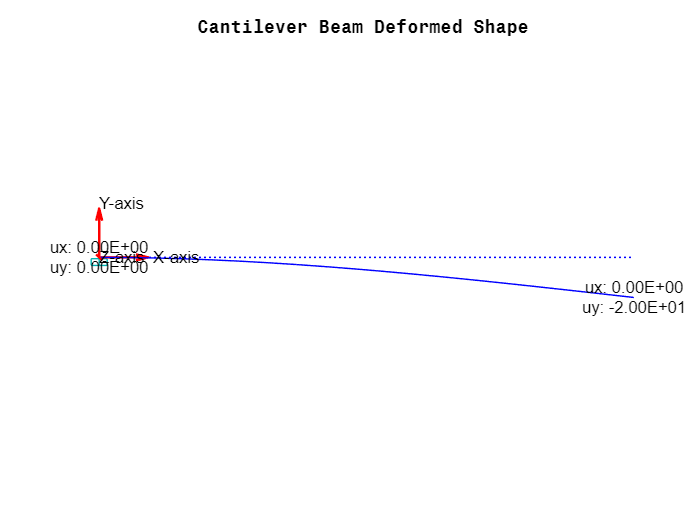

title('Cantilever Beam Deformed Shape'); axis off

compute the maximum y-displacement

maxDisplacement = max(abs(Results.NodalSolution.uy))

maxDisplacement = 20.0000

#### Plot the bending moment diagram

saplab.rplot(cantileverBeamModel,'Diagram', Results.ForcesAndMoments.Mz);

ans =   StructuralModel with properties:

          AnalysisType: "static-planeframe"
              Geometry: [1×1 sap.GeometricModel1D]
    MaterialProperties: [1×1 sap.MaterialPropertiesRecords]
     SectionProperties: [1×1 sap.SectionPropertiesRecords]
      DistributedLoads: [1×1 sap.DistributedLoadsRecords]
             BodyLoads: [1×1 sap.BodyLoadsRecords]
    BoundaryConditions: [1×1 sap.BoundaryConditionRecords]
     ReleaseConditions: []
                  Mesh: [1×1 sap.DiscretizedFEModel]
               Results: [1×1 sap.StructuralResults]


ans = 0

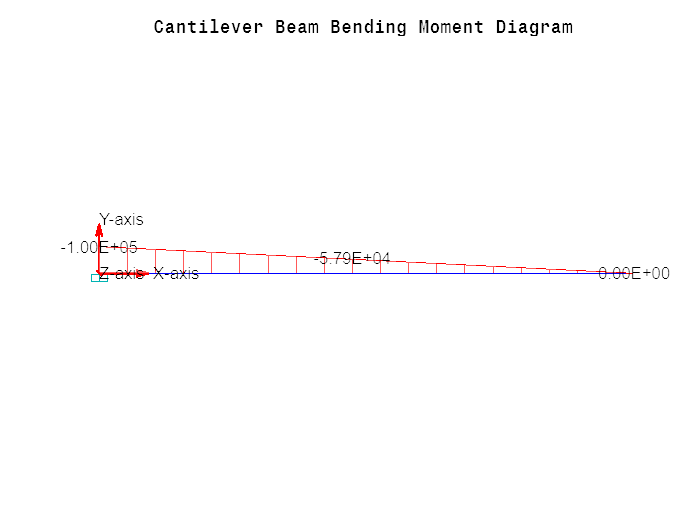

title('Cantilever Beam Bending Moment Diagram');

#### Plot the shear forces diagram

saplab.rplot(cantileverBeamModel,'Diagram', Results.ForcesAndMoments.Ty);

ans = 0

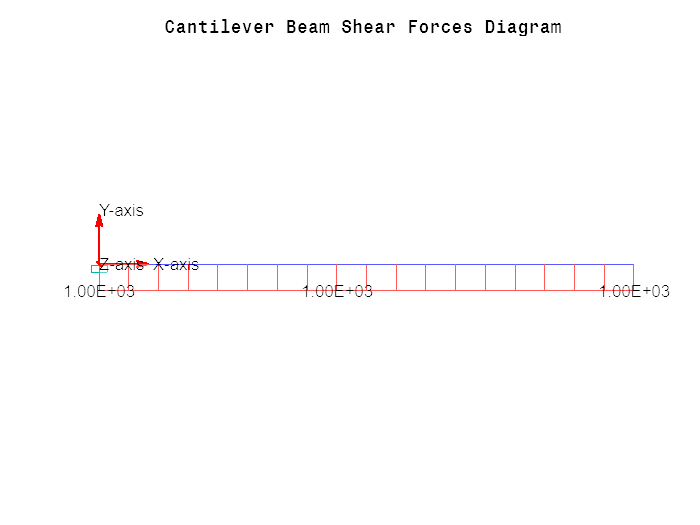

title('Cantilever Beam Shear Forces Diagram');